load SIO Pier data and plot Ts time series

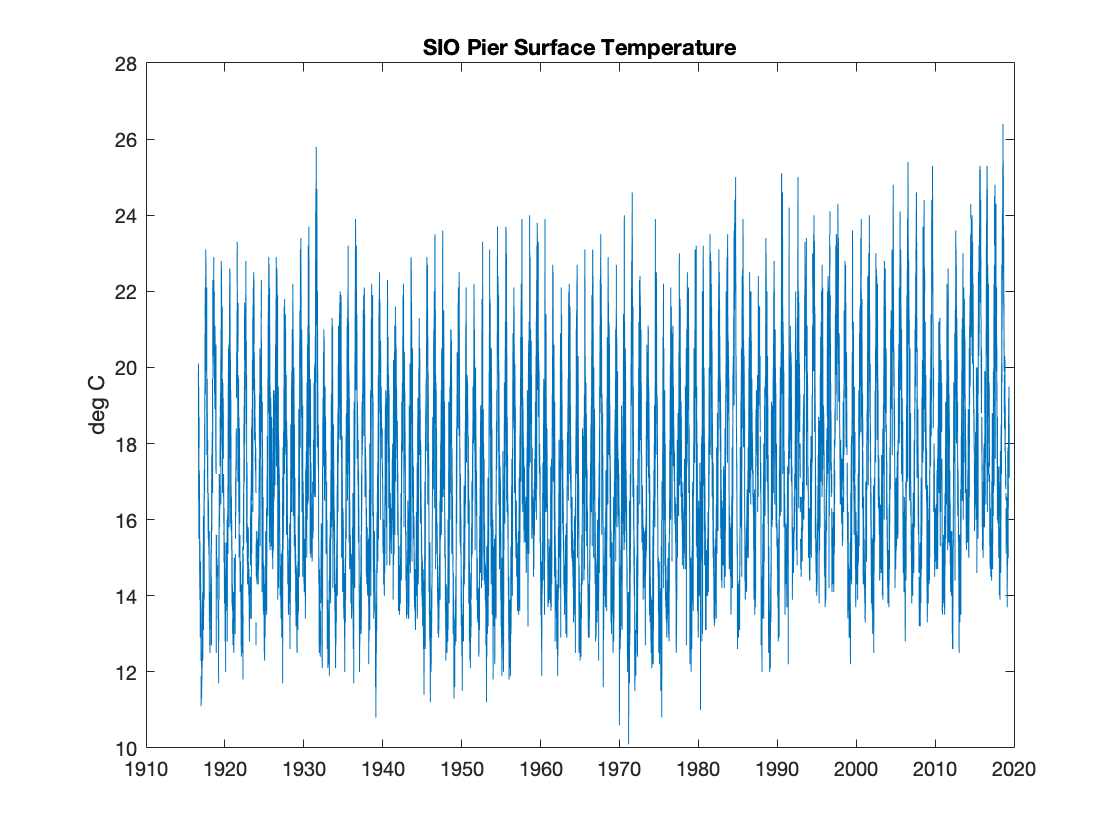

load SIO_PIER_1916_201905.mat

figure (1)
plot(t,Ts)
datetick
ylabel('deg C')
title('SIO Pier Surface Temperature')

Plot one year of data

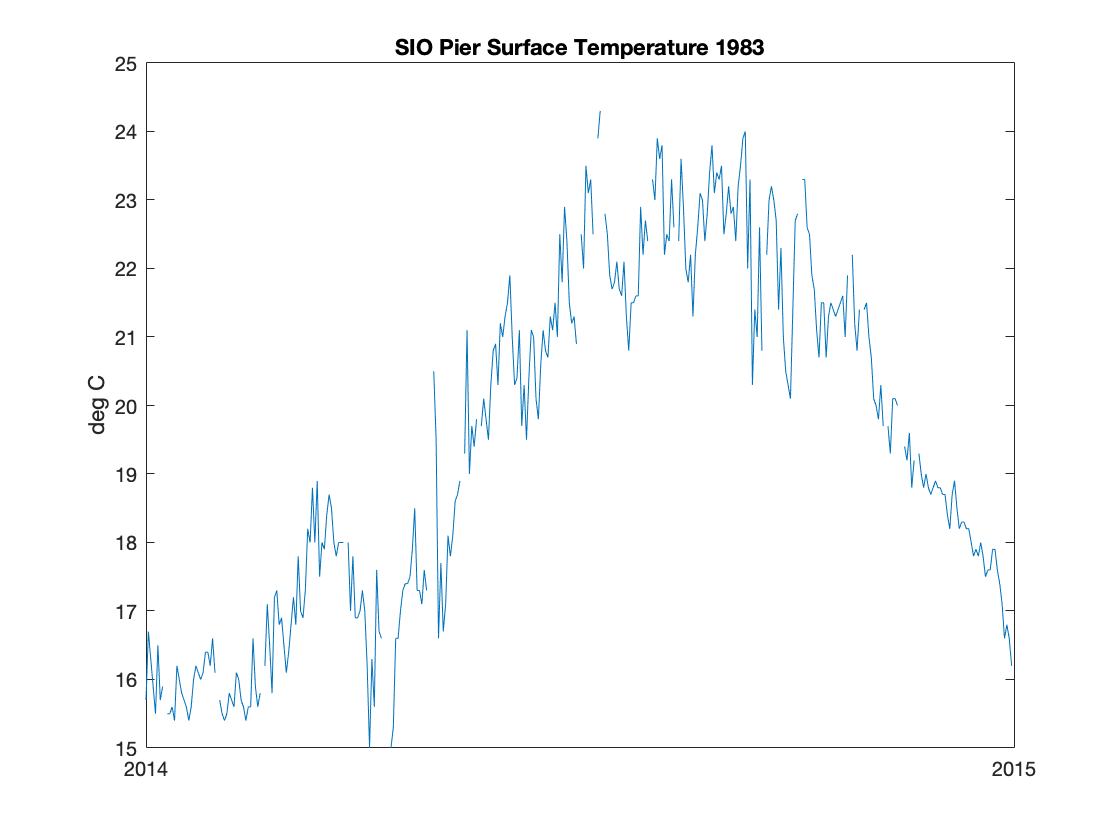

t = datetime(t,'ConvertFrom','datenum');
yr = year(t);
figure (2)
plot(t(yr==2014),Ts(yr==2014))
datetick
ylabel('deg C')
title('SIO Pier Surface Temperature 1983')

Plot one decade

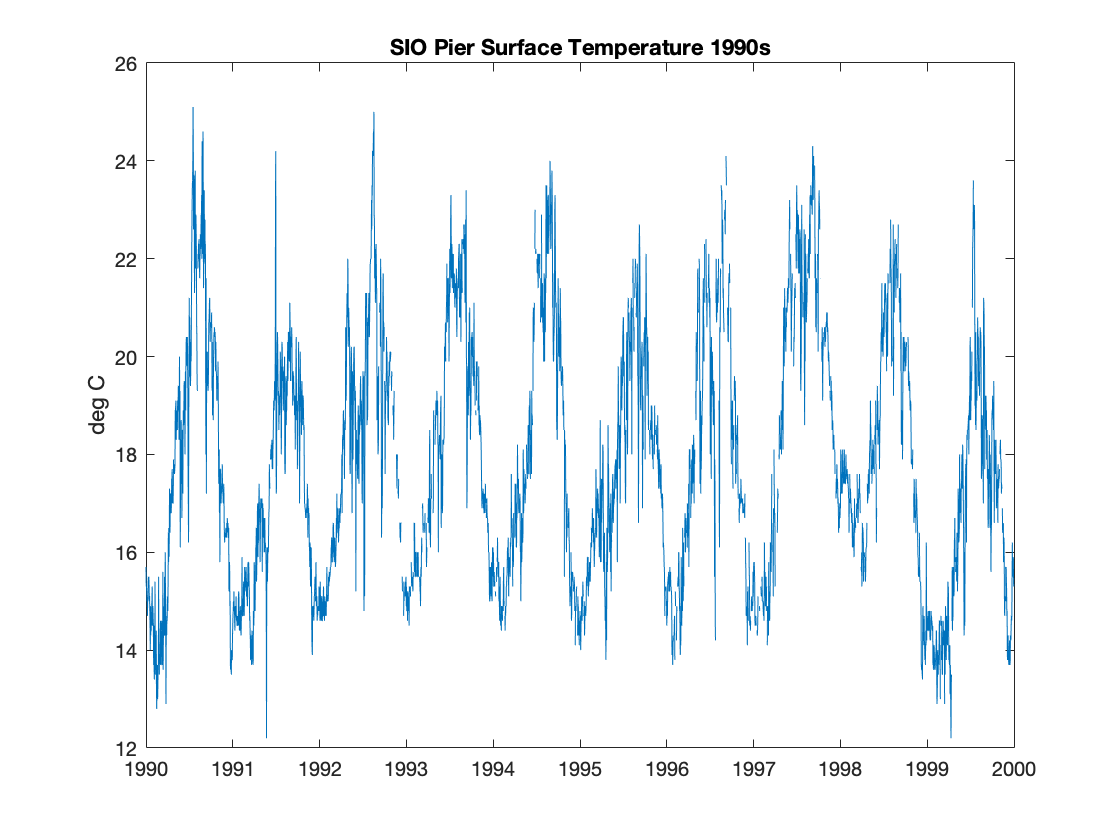

figure (3)
plot(t(yr>=1990 & yr < 2000),Ts(yr>=1990 & yr < 2000))
datetick
ylabel('deg C')
title('SIO Pier Surface Temperature 1990s')

Overplot Dec of major El Nino events, 1982-83, 1997-98, 2015-16

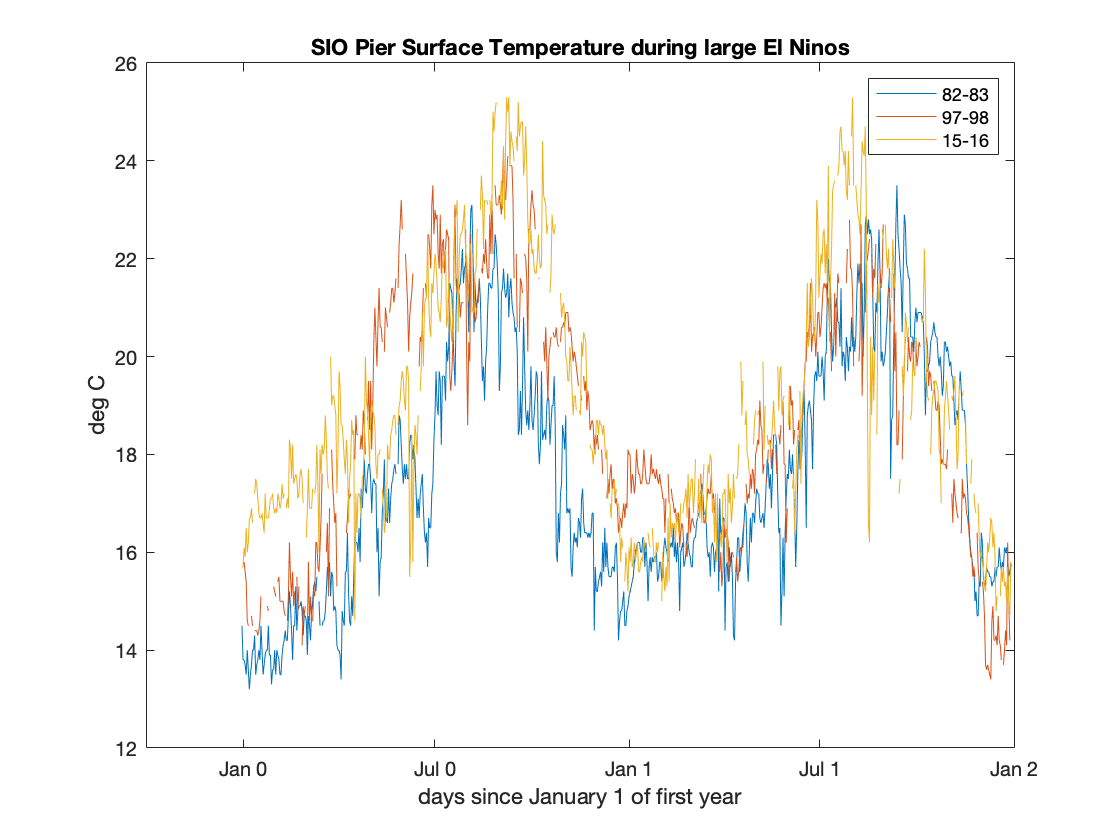

figure (4)
clf
k1 = find(yr>=1982 & yr<=1983);
k2 = find(yr>=1997 & yr<=1998);
k3 = find(yr>=2015 & yr<=2016);
plot(t(k1)-datenum(1982,1,1),Ts(k1))
hold on
plot(t(k2)-datenum(1997,1,1),Ts(k2))
plot(t(k3)-datenum(2015,1,1),Ts(k3))
xlabel('days since January 1 of first year')
ylabel('deg C')
legend('82-83','97-98','15-16')
title('SIO Pier Surface Temperature during large El Ninos')


figure(5);
g = year(t)>2000;
f = year(t)==1983;
tf = t(f)

tf = 365×1 datetime array
   01-Jan-1983 00:00:00
   02-Jan-1983 00:00:00
   03-Jan-1983 00:00:00
   04-Jan-1983 00:00:00
   05-Jan-1983 00:00:00
   06-Jan-1983 00:00:00
   07-Jan-1983 00:00:00
   08-Jan-1983 00:00:00
   09-Jan-1983 00:00:00
   10-Jan-1983 00:00:00
   11-Jan-1983 00:00:00
   12-Jan-1983 00:00:00
   13-Jan-1983 00:00:00
   14-Jan-1983 00:00:00
   15-Jan-1983 00:00:00
   16-Jan-1983 00:00:00
   17-Jan-1983 00:00:00
   18-Jan-1983 00:00:00
   19-Jan-1983 00:00:00
   20-Jan-1983 00:00:00
   21-Jan-1983 00:00:00
   22-Jan-1983 00:00:00
   23-Jan-1983 00:00:00
   24-Jan-1983 00:00:00
   25-Jan-1983 00:00:00
   26-Jan-1983 00:00:00
   27-Jan-1983 00:00:00
   28-Jan-1983 00:00:00
   29-Jan-1983 00:00:00
   30-Jan-1983 00:00:00
   31-Jan-1983 00:00:00
   01-Feb-1983 00:00:00
   02-Feb-1983 00:00:00
   03-Feb-1983 00:00:00
   04-Feb-1983 00:00:00
   05-Feb-1983 00:00:00
   06-Feb-1983 00:00:00
   07-Feb-1983 00:00:00
   08-Feb-1983 00:00:00
   09-Feb-1983 00:00:00
   10-Feb-1983

% plot(t(g),Ss(g))
plot(tf,Ss(f))
% datetick
hold on

Current plot held


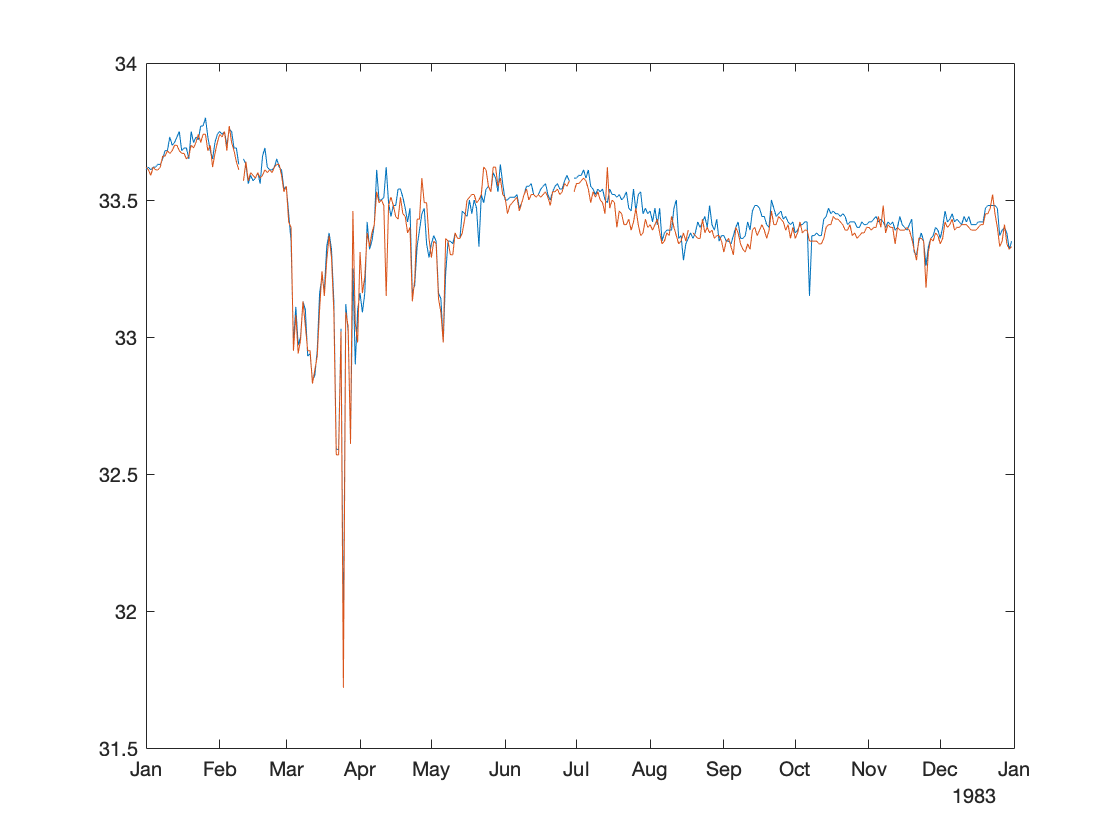

plot(tf,Sb(f))

hold off



